% MATLAB Script to retrieve Git commit history and modified files
% and plot the result as a logical array using the 'spy' function

% created with ChatGPT

% Set the path to your Git repository
repo_path = '.';  % Modify this to your repo path

% Change to the repository directory
cd(repo_path);

% Get the list of commits in the current branch
[~, commitList] = system('git log --pretty=format:"%H"');

% Split the commit list into individual commit hashes
commitHashes = strsplit(strtrim(commitList), '\n');

% Get the list of all files modified in the repository
[~, fileList] = system('git ls-tree -r HEAD --name-only');
files = strsplit(strtrim(fileList), '\n');

% Initialize a logical array for commits vs. files
numCommits = length(commitHashes);
numFiles = length(files);
fileCommitMatrix = false(numCommits, numFiles);

% Loop through each commit and check which files were modified
for i = 1:numCommits
    commitHash = commitHashes{i};
    
    % Get the list of files modified in the current commit
    [~, changedFiles] = system(['git diff-tree --no-commit-id --name-only -r ', commitHash]);
    changedFiles = strsplit(strtrim(changedFiles), '\n');
    
    % For each modified file, set the corresponding entry in the matrix to true
    for j = 1:length(changedFiles)
        file = changedFiles{j};
        
        % Find the index of this file in the file list
        fileIndex = find(strcmp(files, file));
        
        if ~isempty(fileIndex)
            % Set the corresponding position to 1 (true)
            fileCommitMatrix(i, fileIndex) = true;
        end
    end
end

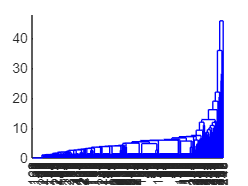

% Calculate the co-occurrence matrix for files (pairwise co-modification)
coOccurrenceMatrix = fileCommitMatrix' * fileCommitMatrix;

% Remove self-co-occurrence (diagonal)
coOccurrenceMatrix = coOccurrenceMatrix - diag(diag(coOccurrenceMatrix));

% Perform hierarchical clustering on the co-occurrence matrix
Z = linkage(coOccurrenceMatrix, 'average');  % 'average' method for linkage
[~, ~, order] = dendrogram(Z, 0);  % Get the cluster order


% Reorder the fileCommitMatrix based on the clustering order
fileCommitMatrixReordered = fileCommitMatrix(:, order);

fileCommitMatrixOrig = fileCommitMatrix;
numCommitsOrig = numCommits;


numCommits = 350;
fileCommitMatrix = fileCommitMatrixOrig(1:numCommits,:);

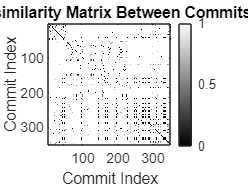

% Compute the pairwise dissimilarity (1 - Jaccard similarity) between all pairs of commits
dissimilarityMatrix = inf(numCommits, numCommits);  % Start with very high cost

for i = 1:numCommits
    for j = i:numCommits
        if i == j
            dissimilarityMatrix(i, j) = 0;  % No dissimilarity for the same commit
        else
            % Jaccard dissimilarity: 1 - Jaccard similarity
            intersection = sum(fileCommitMatrix(i, :) & fileCommitMatrix(j, :));  % Common modified files
            union = sum(fileCommitMatrix(i, :) | fileCommitMatrix(j, :));  % Total modified files
            dissimilarityMatrix(i, j) = 1 - intersection / union;  % Jaccard dissimilarity
            dissimilarityMatrix(j, i) = dissimilarityMatrix(i, j);  % Symmetric matrix
        end
    end
end

% Visualize the dissimilarity matrix with a heatmap (optional)
figure;
imagesc(dissimilarityMatrix);
colorbar;
colormap(gray)
title('Dissimilarity Matrix Between Commits');
xlabel('Commit Index');
ylabel('Commit Index');


% Now, define the number of groups (you can adjust this)
numGroups = 5;

% Initialize the cost matrix for dynamic programming
costMatrix = inf(numCommits, numCommits);  % Start with very high cost for each cut

% Fill the cost matrix based on dissimilarity
for i = 1:numCommits-1
    for j = i+1:numCommits
        % Sum dissimilarity between consecutive commits to calculate the cost of the cut
        costMatrix(i, j) = sum(sum(dissimilarityMatrix(i:j-1, i:j-1)));  % Sum of dissimilarity over the range
    end
end

% dp[i][j] stores the minimum cost to partition the first i commits into j groups
dp = inf(numCommits, numGroups);
dp(1, 1) = 0;  % No cost to partition the first commit into 1 group

% Backtracking table to track the partitions
backtrack = zeros(numCommits, numGroups);


%%%%%%
% Dynamic programming to compute optimal partitioning
for j = 2:numGroups
    for i = j:numCommits
        for k = j-1:i-1
            cost = dp(k, j-1) + costMatrix(k, i);
            if cost < dp(i, j)
                dp(i, j) = cost;
                backtrack(i, j) = k;
            end
        end
    end
end

% Backtrack to find the partition points
partitionPoints = [];
i = numCommits;
j = numGroups;
while j > 1
    partitionPoints = [i, partitionPoints];
    i = backtrack(i, j);
    j = j - 1;
end

Index in position 1 is invalid. Array indices must be positive integers or logical values.

partitionPoints = [1, partitionPoints];  % Start from the first commit


% Plot the partitioning
figure;
hold on;
for i = 1:numGroups
    plot([partitionPoints(i), partitionPoints(i)], [0, numCommits], 'k--', 'LineWidth', 1);
end
hold off;
title('Optimal Partitioning of Commits Based on File Modification Similarity');
xlabel('Commit Index');
ylabel('Group Index');

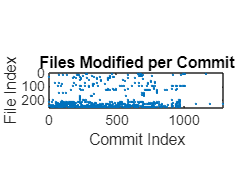


% Visualize the logical array with a sparse matrix plot
figure;
spy(fileCommitMatrixReordered.');
title('Files Modified per Commit');
ylabel('File Index');
xlabel('Commit Index');


matrix = fileCommitMatrix(52:231,:)

matrix = 180×251 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 


count = sum(matrix)

count =      0     0    12     2     0     0     0     0     0     5     0     3     3     0     0     0     1     0     0     0     0     0     1     0     0     2     1     1     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


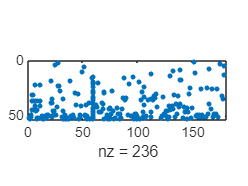


matrixNonzero = matrix(:,count>0);

[~,sortidx] = sort(count(count>0));
newMatrix = matrixNonzero(:,sortidx);

spy(newMatrix.')